# Compute Output of System

Clear Workspace

close all; clearvars; clc

## Load Data

load("Saved_Data_Files/Empty_Tank_10K.mat");

## Initialize Variables

t = (0:N-1)/sampleRate;

## Create a Sample

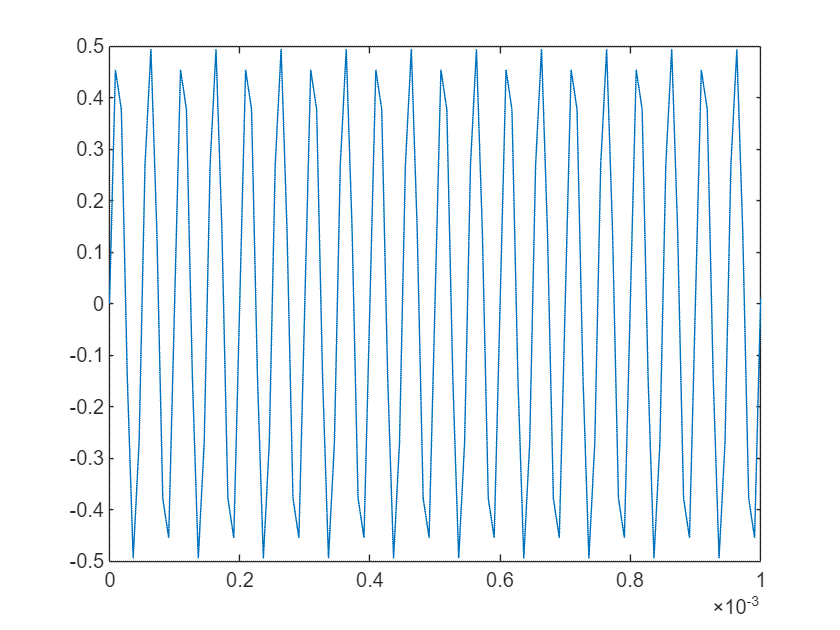

GenWave = createSine(0.5, frq, 0, sampleRate, "bipolar", N);
GenWave = GenWave(1:N);
figure
plot(t, GenWave)
xlim([0 1e-3])

## Come to Measured

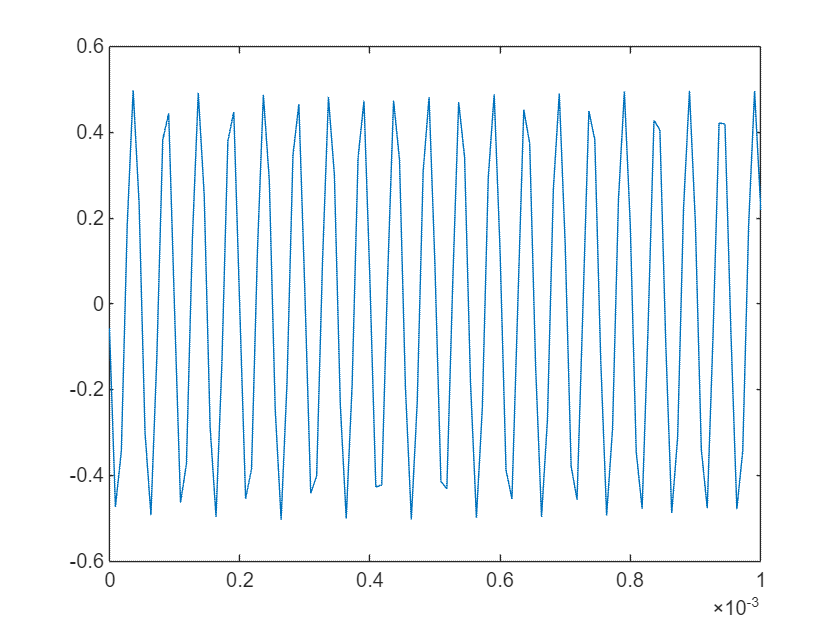

plot(t, squeeze(rawElectrodeData(1,1,:)))
xlim([0 1e-3])

## Compute FFT of First Pattern

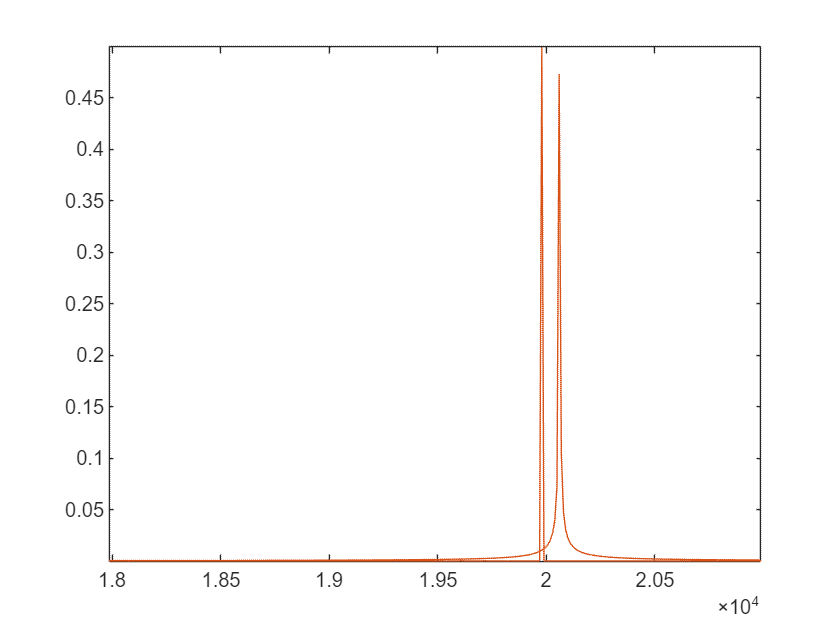

f_Hz = sampleRate/N*(0:N-1);
f_Hz2 = 1e6/N*(0:N-1);
sigFFT = fft(squeeze(rawElectrodeData(1,1,:)));
genFFT = fft(GenWave);

sigNormFFT = abs(sigFFT/N)*2;
genNormFFT = abs(genFFT/N)*2;

figure
plot(f_Hz, sigNormFFT, "-r", f_Hz, genNormFFT, 'Color', "#D95319")
xlim([18e3 21e3])

## Sine Function

function sine = createSine(A, frq, phase, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    period = 1/eval(gcd(sym(frq))); % calculates the length of the period for a periodic signal
    samples = period/timeStep*2-1;
    t = ((0:samples)*timeStep)'; % calculates the time vector from the period
    y = sum(A*sin(2.*pi.*frq.*t+phase),2); % calculates the signal along the time vector
    
    if type == "unipolar"
        y = y + max(y); % if the signal is unipolar add the max amplitude to make it all positive
    end
    
    numCycles = ceil(bufferForPreLoad/(samples+1)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end